# Creación de los Brazos y Articulaciones de un Robot

# Importar ficheros URDF en RigidBody y MultiBody

Dificultad: Alta (Teoría)

## Tipos de ejes de un robot: 

- **Rotacionales**: Un brazo gira respecto del brazo anterior en un nodo.

- **Prismáticos**: Un brazo se desplaza respecto al brazo anterior

- **Fijos**: No se mueven, pero son útiles para definir puntos en el espacio (TCP).

#### Robot industriales antropomórficos:

- Simulan un brazo humano, con antebrazo, brazo y muñeca.

- Suelen tener $6$ grados de libertad, normalmente, $6$ ejes rotacionales.

#### Ejes de un robot

- **Eje base**: Define la referencia de la base del robot.

- **Ejes de los nodos**: Definen la posición de cada nodo. 

- **Eje **$z$** del nodo**: Debe define el giro o traslación del nodo (variable).

- **Punto de trabajo (TCP)**: Eje del último nodo. 

- **Codos**: Ejes $[1,4,6]$, definen la posición del antebrazo, brazo y muñeca. Puede haber $8$ formas de ir a un punto.

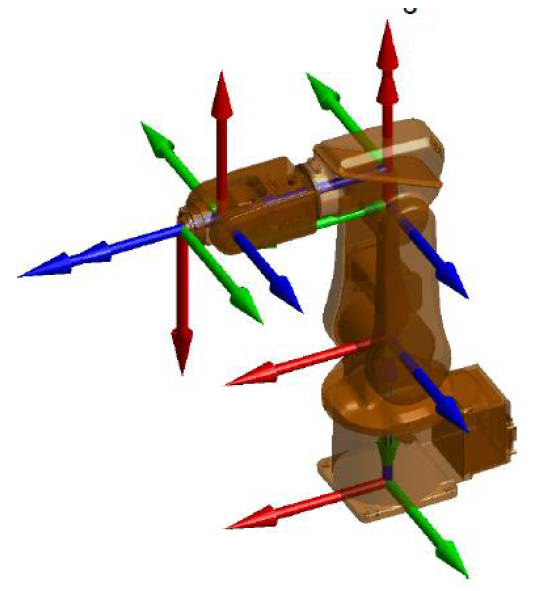

## Formato URDF

- Unified Robot Description Format (URDF) es un archivo XML que permite describir un robot. 

- La descripción del robot consiste en eslabones (*links* rígidos) conectados por medio de las articulaciones (*joints*).

- En el fichero se definen las propiedades geométricas y dinámicas de cada componente del robot.

- Es usado en **Robot Operating System** (**ROS**) para definir sus robots.

- Varios software de CAD pueden exportar sus diseños en formato URDF, lo que hace que en plataformas como [GitHub](https://github.com/) haya muchos robots diseñados en este formato.

## Ejemplo de *link* y *joint* de un fichero URDF

% <link name="link_1">
%     <inertial>
%       <mass value="3.067"/>
%       <origin rpy="0 0 0" xyz="9.77E-05 -0.00012 0.23841"/>
%       <inertia ixx="0.0142175" ixy="-1.28579E-05" ixz="-2.31364E-05" iyy="0.0144041" iyz="1.93404E-05" izz="0.0104533"/>
%     </inertial>
%     <visual>
%       <origin rpy="0 0 0" xyz="0 0 0"/>
%       <geometry>
%         <mesh filename="package://Visual/link_1.stl"/>
%       </geometry>
%       <material name="">
%         <color rgba="0.7372549 0.3490196 0.1607843 1"/>
%       </material>
%     </visual>
% </link>
 
% <joint name="joint_1" type="revolute">
%     <origin rpy="0 0 0" xyz="0 0 0"/>
%     <parent link="base_link"/>
%     <child link="link_1"/>
%     <limit effort="0" lower="-2.87979" upper="2.87979" velocity="4.36332"/>
%     <axis xyz="0 0 1"/>
%     <dynamics damping="0.0" friction="0.0"/>
% </joint>

## Objetos Multi-Body (SimScape Multi-Body) y Rigid-Body (Robotic Toolbox).

- Los objetos Multi-Body se obtienen de la librería de Simulink (SimScape Multibody) y pueden importar los brazos y articulaciones de un robot de un fichero URDF.

- Los objetos Rigid-Body se obtienen de la librería de Matlab (Robotic Toolbox) y también pueden importar los brazos y articulaciones de un robot de un fichero URDF.

- Los objetos Rigid-Body pueden importar el robot del fichero Simulink Multibody.

Esta librería va a emplear ambos objetos para mover un robot. 

- El objeto Rigid-Body se usará para definir la trayectoria ya que tiene cinemática inversa. 

- El objeto Multi-Body se usa para crear una estación y simular el movimiento.

- El objeto $Cin$, base de esta librería, coordina ambos entornos, "pensar" la trayectoria y simularla.

## Ficheros URDF ya importados en RigidBody en ficheros **.mat*

- La librería Robotic Toolbox tiene bastantes robots en estructura de RigidBody definida en ficheros *.mat. Dichos ficheros han sido importados de los ficheros URDF.

- En la página [URDF de la Librería Robotic Toolbox](https://github.com/mathworks/Industrial-Robots-Simscape/tree/master) se puede acceder a los ficheros URDF de dichos robots.

- En el apéndice se muestran el nombre de los modelos y una descripción de los mismos.

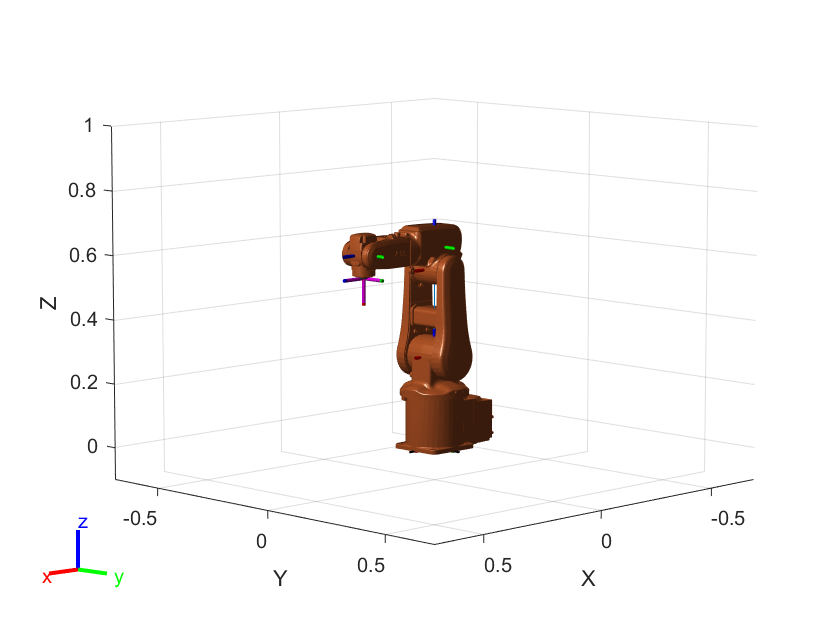

deg= pi/180;
load("abbIrb120.mat")
%robotData.Source
robot.DataFormat = 'column';
q= [0,0,0,0,90,0]'*deg;
show(robot,q);

axis([-700,700,-700,700,-100,1000]*1e-3)

## Importar directamente un fichero URDF y ficheros **.stl* a RigidBody

- El primer paso es importar la estructura del fichero a RigidBody.

- De forma directa se puede dar la carpeta donde están los ficheros **.stl* para unirlos.

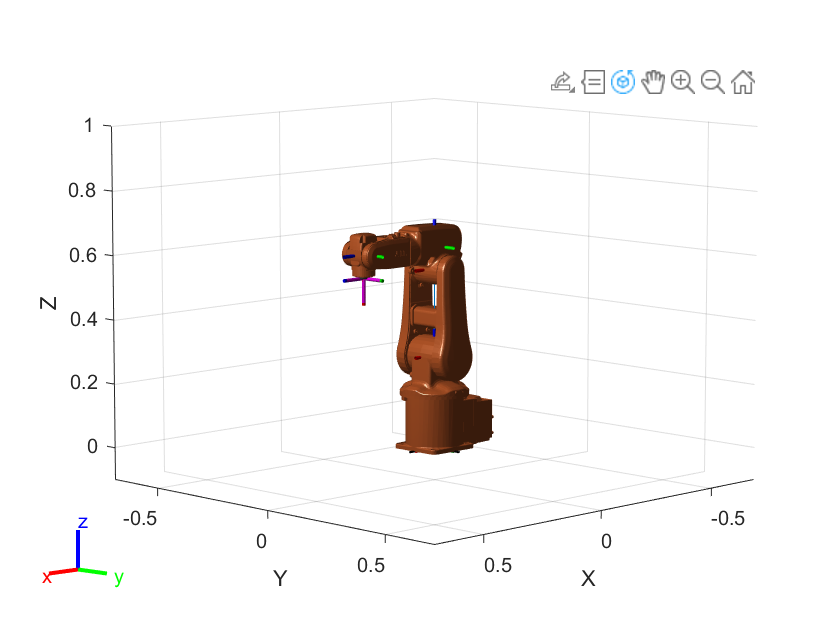

p= pwd; % Carpeta actual
robpath= './Robots/abbIrb120';
rob= importrobot([robpath,'/robot.urdf'], 'MeshPath', [p,'robpath']);
rob.DataFormat = 'column';

q= [0,0,0,0,90,0]'*deg;
show(robot,q);

axis([-700,700,-700,700,-100,1000]*1e-3)

## Importar ficheros URDF a objetos Multi-Body

- La librería SimScape puede importar ficheros URDF sin actuadores ni sensores.

robpath= './Robots/abbIrb120';
smimport([robpath,'/robot.urdf'])

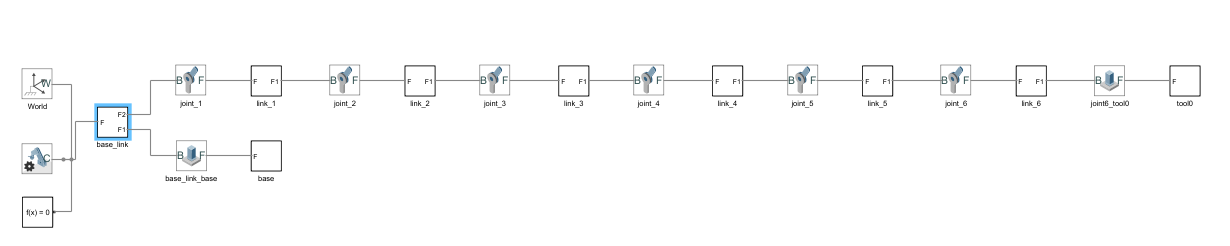

- Cada *link* tiene los parámetros geometricos, dinámicos y visuales correspondientes al fichero URDF. Modifcar los ficheros Visual para introducir en cada eslabón el fichero **.stl* correspondiente.

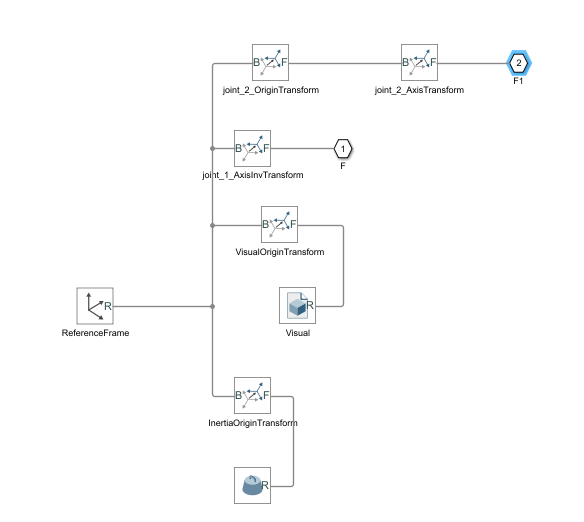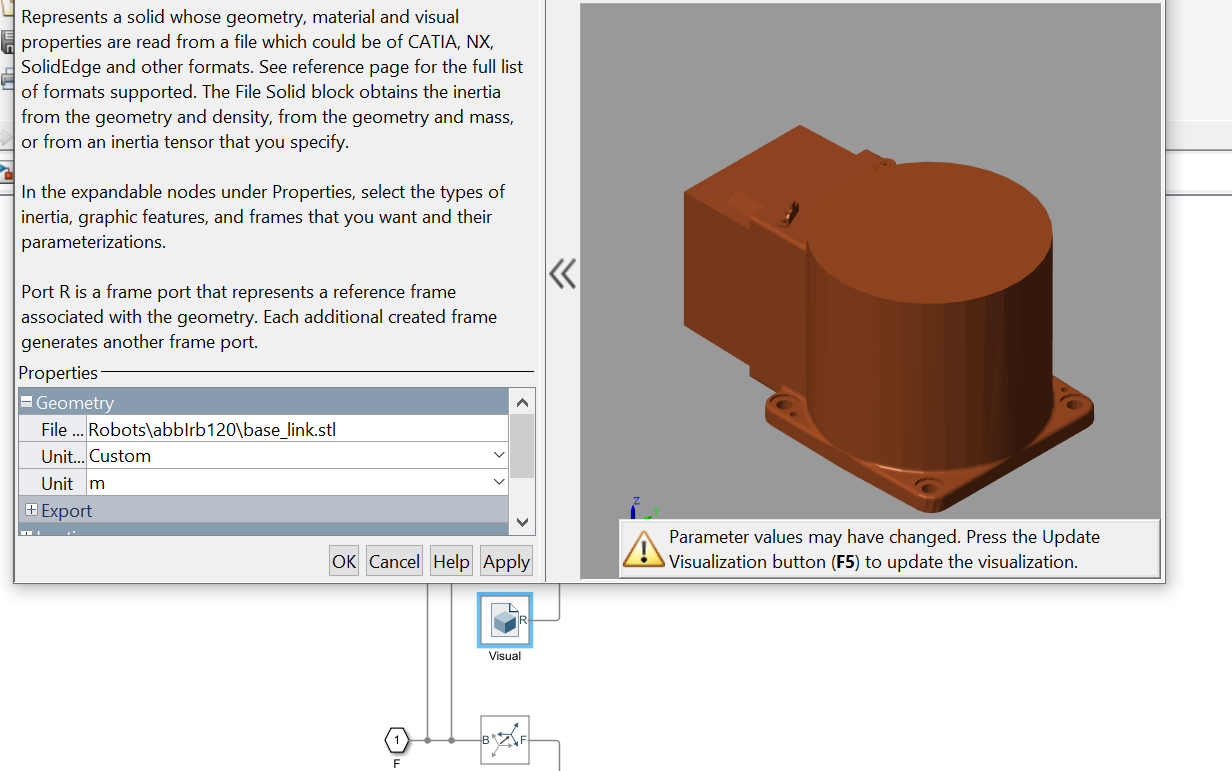

- Añadir los actuadores correspondientes a un robot cinemático o dinámico.

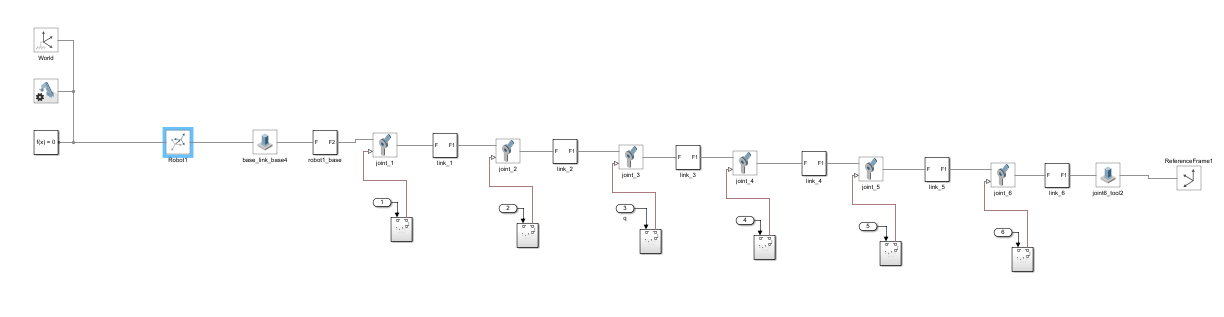

- La entrada posición ángular debe se introducida con sus dos derivadas para una simulación cinemática.

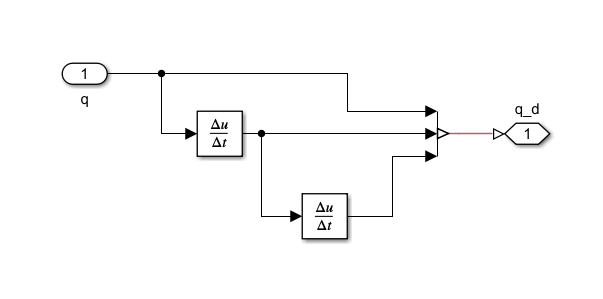

## Simulación de un robot básico

deg= pi/180;

Estacion= 'T25S1_irb120_basico';
% Variables
baseRobot= [[0,0,0],[0,0,0]*deg];
% Posición inicial 
q0_= [0,0,0,0,0,0]*deg;
% Rastreador (ahora no se usa)
pose_= rand(3,3)*1e-3;

open_system(Estacion);

% Movimiento en joint de inicial a final
qend= [0,20,30,-50,90,0]*deg;

nPts= 1e2;
t= linspace(0,10,nPts)';
q= zeros(nPts,6);
for i= 1:6
   q(:,i)= linspace(q0_(i),qend(i),nPts)';
end

sim(Estacion,t, [], [t,q]);

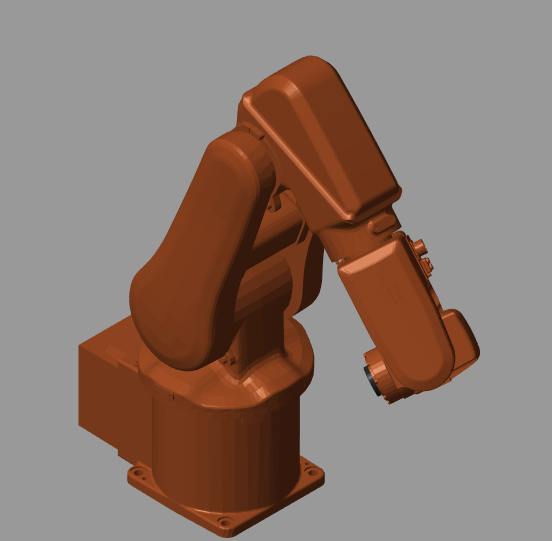

## Iconos de robots en SimRobots

- Introducir el robot en un icono y crear una máscara, para que quede más compacto.

- La entrada del subsistema es la variable $baseRobot$, que define la posición del robot y $q0\_$ que define las posiciones iniciales.

- Todo ello ya se ha hecho con números robots, que son los que se va han a usar en el curso.

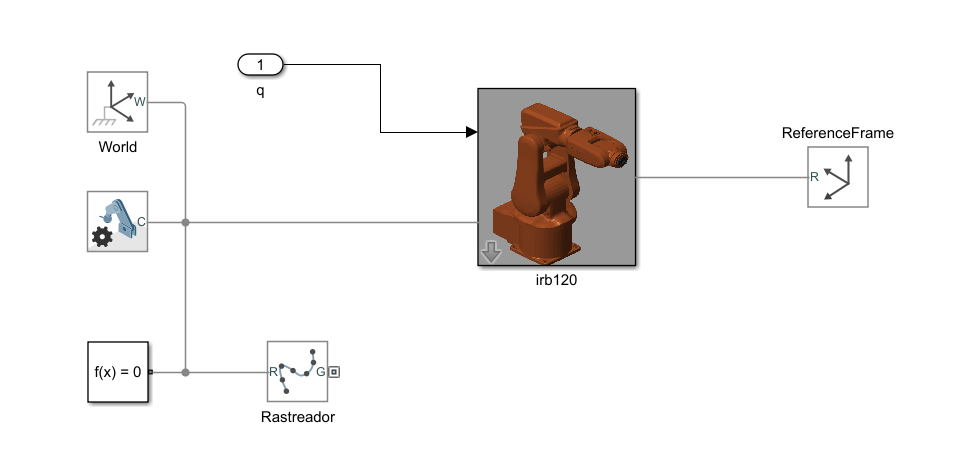

Modelo= 'T25S2_irb120';
nPts= 1e3;
deg= pi/180; % conversor

% Base del robot
baseRobot= [0,0,0,0,0,0];
% q inicial
q0_= [0,0,0,0,0,0];

t= linspace(0,10,nPts)';

theta= zeros(nPts,6);

% Se mueve 30 grados desde la posición inicial
for i= 1:6
   theta(:,i)= linspace(q0_(i)*deg, (q0_(i)+30)*deg, nPts)';
end

open_system(Modelo)
sim(Modelo, t, [], [t,theta]);


## Comparación entre Multi-Body y Rigid-Body

- La simulación en Multi-Body sobre el entorno *Explore *es mucho más interesante que la de Rigid-Body.

- Además, en Multi-Body se puede simular una estación completa, compuesta de varios robots y otros objetos.

- Multi-Body solo simula, no puede calcular trayectorias, que sí puede hacerlo Rigid-Body.

- La colaboración entre ambos objetos es la base de esta librería. 

## Importar objetos Rigid-Body desde objetos Multi-Body

- Los objetos Multi-body pueden ser importados a Rigid-Body sin sus archivos visuales.

- Puede ser importante para calcular trayectorias en Rigid-Body de la estación Multi-Body.

robot= importrobot(Estacion);
robot.showdetails

--------------------
Robot: (8 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1         fixed             Base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   Body7(7)  
   7        Body7        Joint7      revolute            Body6(6)   Body8(8)  
   8        Body8        Joint8         fixed            Body7(7)   
--------------------


## Robot importados en ficheros **.mat* de ficheros URDF en *Robotic Toolbox*

% abbIrb120.urdf                                    
% abbIrb120T.urdf                                                              
% abbIrb1600.urdf                                                                  
% abbYuMi.urdf                                      
% amrPioneer3AT.urdf            (Carro con 4 ruedas)                       
% amrPioneer3DX.urdf            (Carro con 3 ruedas)                       
% amrPioneerLX.urdf             (Carro con 4 ruedas)                                                    
% atlas.urdf                    (Humanoide con bolas en los pies)                                                           
% clearpathHusky.urdf           (Carro con 4 ruedas)                                                  
% clearpathJackal.urdf          (Carro con 4 ruedas)                       
% clearpathTurtleBot2.urdf      (Estantería con ruedas                                             
% fanucLRMate200ib.urdf         (Robot 6DOF pequeño)                                                   
% fanucM16ib.urdf                                                          
% frankaEmikaPanda.urdf         (Robot  6DOF convencional)                                             
% kinovaGen3.urdf               (similar al ur3, sin pinza)                                                        
% kinovaJacoJ2N6S200.urdf       (con pinza típica de 3 dedos)                       
% kinovaJacoJ2N6S300.urdf                           
% kinovaJacoJ2N7S300.urdf                           
% kinovaJacoJ2S6S300.urdf                           
% kinovaJacoJ2S7S300.urdf                           
% kinovaJacoTwoArmExample.urdf                      
% kinovaMicoM1N4S200.urdf                           
% kinovaMicoM1N6S200.urdf                           
% kinovaMicoM1N6S300.urdf                                                   
% kinovaMovo.urdf               (móvil con dos brazos, urdf con xacro)                                                        
% rethinkBaxter.urdf            (ruedas tipo silla, dos brazos y visión)                                                     
% robotisOP2.urdf               (Humanoide pequeño tipo japones)                            
% robotisOpenManipulator.urdf   (robot 6DOF con una gran pinza)                     
% robotisTurtleBot3Burger.urdf  (estantería con ruedas)                    
% robotisTurtleBot3Waffle.urdf                      
% robotisTurtleBot3WaffleForOpenManipulator.urdf    
% robotisTurtleBot3WafflePi.urdf                    
% robotisTurtleBot3WafflePiForOpenManipulator.urdf               
% universalUR10.urdf                                
% universalUR3.urdf                                 
% universalUR5.urdf                                                      
% valkyrie.urdf                 (humanoide)                                                     
% willowgaragePR2.urdf          (móvil con dos brazos)                                             
% yaskawaMotomanMH5.urdf        (robot 6DOF pequeño)                       